## PROIECT – Structura de poziționare PUMA cu 3 cuple

Robot simulat în mediul virtual: model cinematic și model dinamic, urmărirea traiectoriei r(t), acționări și control PI

**Universitatea Transilvania din Brașov**

**Specializarea:** Robotică

**Realizat de:** Stefan Horia - Eusebiu

**Grupa / An de studiu: 4LF832 / Anul IV**

**Profesor coordonator:** Prof. Dr.-Ing. Claudiu Pozna

## Structura lucrării

- Descrierea structurii PUMA și a sistemelor de coordonate

- Modelul geometric direct și invers

- Modelul cinematic (Jacobian, viteze, accelerații) și urmărirea traiectoriei r(t)

- Modelul dinamic (Lagrange): M(q), C(q,dq), G(q)

- Dinamica inversă, dinamica directă și validarea modelului

- Alegerea acționărilor: motor de curent continuu + reductor planetar

- Modelul acționării și acordarea regulatoarelor PI prin alocarea polilor

- Modelul Simulink al sistemului de reglare (contrPUMA.slx)

- Rezultatele simulării în buclă închisă (urmărirea r(t))

- Concluzii

## 1. Structura robotului

Structura de poziționare PUMA are 3 cuple de rotație. Prima cuplă rotește tot brațul în jurul axei verticale z, iar cuplele 2 și 3 rotesc brațul și antebrațul în jurul axei y (umăr și cot). Axele {0}: x orizontal, z vertical în sus.

- C1 = Rz(q1) – rotația bazei, la înălțimea l1

- C2 = Ry(q2) – umărul, deplasat cu l3 pe x și l2 pe z față de {1}

- C3 = Ry(q3) – cotul, la distanța l4 de umăr

- Efectorul E se află la distanța le de cot

Matricile de transformare omogenă (exact ca în calculul de pe schiță):

`0_1T = [ Rz(q1)  (0, 0, l1)  ]      1_2T = [ Ry(q2)  (l3, 0, l2) ]`

`2_3T = [ Ry(q3)  (l4, 0, 0)  ]      3_eT = [ I3      (le, 0, 0)  ]`

`Rz(q) = [ c -s 0 ;  s c 0 ;  0 0 1 ]      Ry(q) = [ c 0 s ;  0 1 0 ; -s 0 c ]`

`0_2T = 0_1T·1_2T      0_3T = 0_2T·2_3T      0_eT = 0_3T·3_eT`

Convenția de semn rezultată din Ry: q2 > 0 și q3 > 0 coboară brațul (axa x se rotește spre −z).

Tot codul este în acest singur fișier: scriptul principal sus, funcțiile locale la final. Dimensiunile, masele și momentele de inerție sunt definite în funcția **parametri_PUMA** (elementele sunt cilindri omogeni din aluminiu, plus o sarcină utilă mp în E). Aceleași valori trebuie folosite în modelul Simscape, pentru ca rezultatele să fie comparabile. Etapa de control (secțiunile 9–13) folosește funcția PUMA_simulare.m din același folder, care conține codul complet al proiectului (aceleași modele, plus acționările, regulatoarele și construirea modelului Simulink).

clear; clc; close all;

par = parametri_PUMA();

## 2. Modelul geometric direct și vizualizarea robotului

Prin înmulțirea matricilor se obține poziția efectorului:

`x = cos(q1)·(l3 + l4·cos(q2) + le·cos(q2+q3))`

`y = sin(q1)·(l3 + l4·cos(q2) + le·cos(q2+q3))`

`z = l1 + l2 − l4·sin(q2) − le·sin(q2+q3)`

Funcția **[p, T0e] = geometric(q, par, f)** întoarce poziția și matricea 0_eT; cu f = 1 deschide fereastra **Braț Robotic – Vizualizare Complexă**:

- Vedere 3D – robotul desenat din cilindri: elementele albastre, cuplele roșii (orientate după axa de rotație), sistemul {e} al efectorului cu axele X, Y, Z;

- Proiecție Plan XY (de sus) și Proiecție Plan YZ (din lateral);

- titlul afișează unghiurile cuplelor în grade; în animații se desenează și urma efectorului (mov) și traiectoria dorită (punctat).

Fiecare piesă este definită o singură dată în cadrul ei ({1}, {2}, {3}, {e}) și este mutată cu matricile 0_1T, 0_2T, 0_3T, 0_eT – vizualizarea folosește direct modelul geometric. Afișarea este în cm.

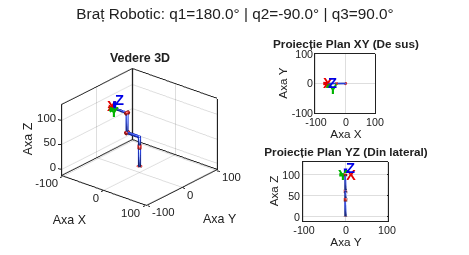

q_test = [pi; -pi/2; pi/2];            % [180°  -90°  90°]
[p_test, T0e] = geometric(q_test, par, 1);

disp('0_eT = '); disp(T0e);

0_eT = 
   -1.0000   -0.0000         0   -0.6000
    0.0000   -1.0000         0    0.0000
         0         0    1.0000    1.0000
         0         0         0    1.0000



## 3. Modelul geometric invers – geometric_invers

Necesar pentru urmărirea traiectoriei r(t): din poziția dorită a efectorului se calculează unghiurile cuplelor.

`q1  = atan2(y, x)`

`rho = sqrt(x² + y²) − l3          h = l1 + l2 − z`

`cos(q3) = (rho² + h² − l4² − le²) / (2·l4·le)`

`q3  = atan2(cot·sqrt(1 − cos²(q3)), cos(q3))        cot = +1 (cot sus) / −1 (cot jos)`

`q2  = atan2(h, rho) − atan2(le·sin(q3), l4 + le·cos(q3))`

q_t = [pi/6; -pi/6; pi/3];
p_t = geometric(q_t, par);
q_inv = geometric_invers(p_t, par, +1);
fprintf('q impus   = [%8.4f %8.4f %8.4f]\n', q_t);

q impus   = [  0.5236  -0.5236   1.0472]


fprintf('q din MGI = [%8.4f %8.4f %8.4f]\n', q_inv);

q din MGI = [  0.5236  -0.5236   1.0472]


fprintf('eroare MGI: %.2e\n', norm(q_inv - q_t));

eroare MGI: 1.57e-16


## 4. Modelul cinematic – jacobian_PUMA, cinematica_directa

Vitezele și accelerațiile efectorului se obțin cu Jacobianul geometric J = [Jv; Jw] (6×3):

`v = Jv·dq          a = Jv·ddq + dJv·dq          w = Jw·dq`

`r = l3 + l4·c2 + le·c23           a = l4·s2 + le·s23`

`Jv = [ −s1·r   −c1·a   −c1·le·s23`

`        c1·r   −s1·a   −s1·le·s23`

`         0     −(l4·c2 + le·c23)   −le·c23 ]`

`Jw = [ 0  −s1  −s1`

`       0   c1   c1`

`       1    0    0 ]`

Mișcarea în spațiul cuplelor se generează cu **traiect** (preluată din proiectul anterior și extinsă la n coordonate). Pe lângă polinomul cubic, funcția are și varianta de grad 5, care pornește și oprește mișcarea cu accelerație nulă – cuplurile din modelul dinamic nu mai au salturi la capete.

`grad 3:  s(τ) = 3τ² − 2τ³`

`grad 5:  s(τ) = 10τ³ − 15τ⁴ + 6τ⁵          τ = t/T,   q(t) = q0 + (qf − q0)·s(τ)`

Verificare: viteza obținută cu Jacobianul este comparată cu derivata numerică a poziției.

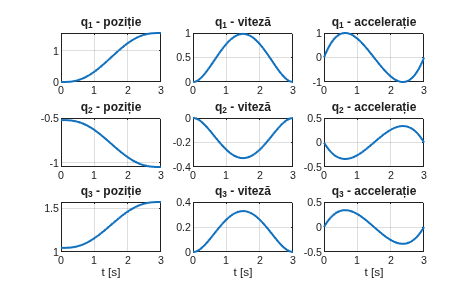

T = 3;  N = 151;
q_lim = [0,      pi/2;      % q1
         -pi/6, -pi/3;      % q2
          pi/3,  pi/2];     % q3
[pvc, t] = traiect(q_lim, T, N, 5, 1, {'q_1','q_2','q_3'});

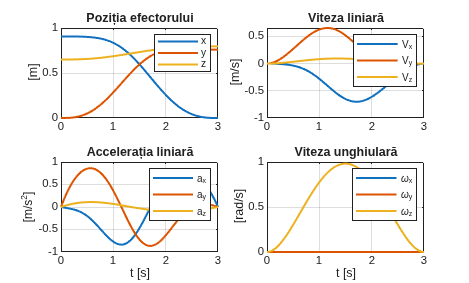

Q = pvc(1:3,:);  dQ = pvc(4:6,:);  ddQ = pvc(7:9,:);

[P, V, A, W] = cinematica_directa(Q, dQ, ddQ, t, par, 1);

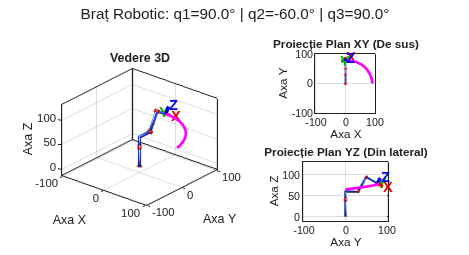

animatie(Q, par);


% verificare: viteza din Jacobian = derivata numerică a poziției
V_num = gradient(P, t(2) - t(1));
fprintf('Verificare Jacobian (v = J*dq vs. dp/dt numeric): %.2e m/s\n', ...
        max(max(abs(V(:,2:end-1) - V_num(:,2:end-1)))));

Verificare Jacobian (v = J*dq vs. dp/dt numeric): 2.03e-04 m/s


## 5. Urmărirea traiectoriei r(t) – cinematica_inversa

Efectorului i se impune o traiectorie carteziană r(t) (aici un segment de dreaptă între pA și pB, cu lege de grad 5). Mărimile de referință pentru cuple rezultă din modelul cinematic invers:

`q   = MGI(r)`

`dq  = Jv⁻¹·dr`

`ddq = Jv⁻¹·(ddr − dJv·dq)`

Aceste referințe q(t), dq(t), ddq(t) sunt intrarea pentru modelul dinamic și, mai departe, pentru regulatoare. Verificare: cinematica directă aplicată rezultatului trebuie să reproducă r(t).

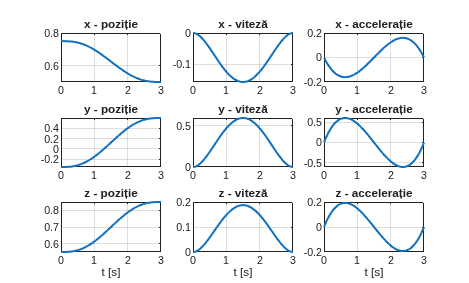

% Efectorul parcurge un segment de dreaptă între pA și pB, cu lege de grad 5.
pA = [0.75; -0.35; 0.55];
pB = [0.50;  0.60; 0.85];
[rvc, t] = traiect([pA pB], T, N, 5, 1, {'x','y','z'});

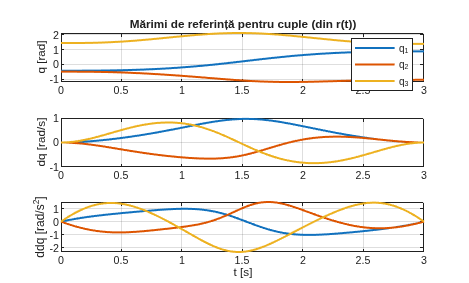

R = rvc(1:3,:);  dR = rvc(4:6,:);  ddR = rvc(7:9,:);

[Qd, dQd, ddQd] = cinematica_inversa(R, dR, ddR, par, +1);

figure('Name', 'Cuple pentru urmărirea r(t)');
subplot(3,1,1); plot(t, Qd,   'LineWidth', 1.5); grid on; ylabel('q [rad]');      legend('q_1','q_2','q_3');
title('Mărimi de referință pentru cuple (din r(t))');
subplot(3,1,2); plot(t, dQd,  'LineWidth', 1.5); grid on; ylabel('dq [rad/s]');
subplot(3,1,3); plot(t, ddQd, 'LineWidth', 1.5); grid on; ylabel('ddq [rad/s^2]'); xlabel('t [s]');


% verificare: cinematica directă aplicată rezultatului reproduce r(t)
[Pc, Vc, Ac] = cinematica_directa(Qd, dQd, ddQd, t, par, 0);
fprintf('Urmărire r(t): eroare poziție %.2e m, viteză %.2e m/s, accelerație %.2e m/s^2\n', ...
        max(abs(Pc(:) - R(:))), max(abs(Vc(:) - dR(:))), max(abs(Ac(:) - ddR(:))));

Urmărire r(t): eroare poziție 2.22e-16 m, viteză 1.11e-16 m/s, accelerație 2.71e-16 m/s^2


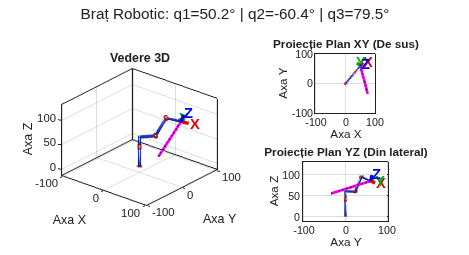


animatie(Qd, par, R);

## 6. Modelul dinamic – model_dinamic

Ecuațiile de mișcare s-au obținut prin metoda Lagrange (L = T − V):

`M(q)·ddq + C(q,dq)·dq + G(q) + Fv·dq = τ`

Centrele de masă (lc2, lc3 – distanțe pe axa elementului) și vitezele unghiulare în axele proprii:

`r_c2 = l3 + lc2·c2                 z_c2 = l1 + l2 − lc2·s2`

`r_c3 = l3 + l4·c2 + lc3·c23        z_c3 = l1 + l2 − l4·s2 − lc3·s23`

`w2 = [−s2·dq1 ; dq2 ; c2·dq1]      w3 = [−s23·dq1 ; dq2+dq3 ; c23·dq1]`

Matricea maselor (M12 = M13 = 0, pentru că axa umărului trece prin axa bazei):

`M11 = I1zz + I2xx·s2² + I2zz·c2² + I3xx·s23² + I3zz·c23² + m2·r_c2² + m3·r_c3²`

`M22 = I2yy + m2·lc2² + I3yy + m3·(l4² + lc3² + 2·l4·lc3·c3)`

`M23 = I3yy + m3·(lc3² + l4·lc3·c3)`

`M33 = I3yy + m3·lc3²`

Matricea Coriolis/centrifugală (simboluri Christoffel), cu h2 = ½·∂M11/∂q2, h3 = ½·∂M11/∂q3, h = m3·l4·lc3·s3:

`C = [  h2·dq2 + h3·dq3    h2·dq1      h3·dq1`

`      −h2·dq1            −h·dq3      −h·(dq2+dq3)`

`      −h3·dq1             h·dq2       0          ]`

Vectorul gravitațional G = ∂V/∂q:

`G = [ 0 ;  −g·(m2·lc2·c2 + m3·(l4·c2 + lc3·c23)) ;  −g·m3·lc3·c23 ]`

Verificări: M este simetrică și pozitiv definită, iar dM/dt − 2C este antisimetrică (proprietate a formei Christoffel).

q0 = Qd(:,1);  dq0 = [0.3; -0.2; 0.5];
[M, C, G] = model_dinamic(q0, dq0, par);
disp('M(q) = '); disp(M);

M(q) = 
    2.3928         0         0
         0    0.7751    0.1396
         0    0.1396    0.1142



disp('C(q,dq) = '); disp(C);

C(q,dq) = 
   -0.2063    0.0745   -0.0940
   -0.0745   -0.0979   -0.0587
    0.0940   -0.0392         0



disp('G(q) = '); disp(G);

G(q) = 
         0
  -17.7091
   -2.8549



fprintf('M simetrică: %d,  valori proprii M: %s\n', isequal(M, M.'), mat2str(eig(M).', 4));

M simetrică: 1,  valori proprii M: [0.08592 0.8034 2.393]



% proprietatea de antisimetrie: dM/dt - 2C este antisimetrică
e = 1e-6;
Mdot = (model_dinamic(q0 + e*dq0, [], par) - model_dinamic(q0 - e*dq0, [], par))/(2*e);
S = Mdot - 2*C;
fprintf('Verificare antisimetrie (dM/dt - 2C): %.2e\n', norm(S + S.'));

Verificare antisimetrie (dM/dt - 2C): 6.35e-10


## 7. Dinamica inversă – dinamica_inversa

Cuplurile necesare pentru urmărirea r(t): τ = M·ddq + C·dq + G + Fv·dq. Graficul arată și componentele inerțială, Coriolis și gravitațională – cupla 1 nu are componentă gravitațională, iar la cuplele 2 și 3 gravitația este dominantă.

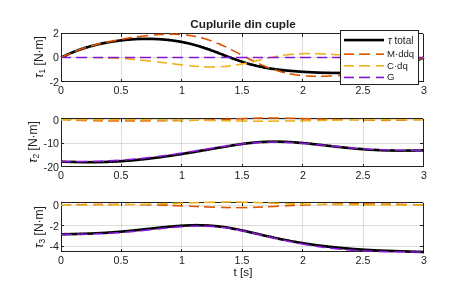

Tau = dinamica_inversa(Qd, dQd, ddQd, t, par, 1);

## 8. Dinamica directă și validarea modelului – dinamica_directa, simulare_dinamica

`ddq = M(q)⁻¹·(τ − C(q,dq)·dq − G(q) − Fv·dq)          x = [q ; dq],  integrare cu ode45`

- Cuplurile din dinamica inversă, aplicate modelului direct, trebuie să reproducă traiectoria dorită.

- În mișcare liberă (τ = 0, fără frecare) energia totală E = ½·dqᵀ·M·dq + V trebuie să rămână constantă.

Funcția **dinamica_directa(t, x, tau_fun, par)** primește cuplul ca funcție tau_fun(t, x), deci aceeași funcție se poate folosi mai departe cu o lege de reglare (ex. PD + compensarea gravitației) pentru urmărirea r(t) în buclă închisă.

% Verificare punctuală: ddq = M^-1*(tau - C*dq - G) trebuie să dea exact ddq dorit
err_dd = 0;
for i = 1:N
    [Mi, Ci, Gi] = model_dinamic(Qd(:,i), dQd(:,i), par);
    err_dd = max(err_dd, norm(Mi \ (Tau(:,i) - Ci*dQd(:,i) - Gi - par.Fv(:).*dQd(:,i)) - ddQd(:,i)));
end
fprintf('Dinamica directă(dinamica inversă): eroare accelerații %.2e rad/s^2\n', err_dd);

Dinamica directă(dinamica inversă): eroare accelerații 8.10e-15 rad/s^2



% 7a. Buclă deschisă: cuplurile de la punctul 6 aplicate modelului direct
%     trebuie să reproducă mișcarea dorită (validarea modelului).
%     Obs.: sistemul în buclă deschisă este foarte sensibil (gravitația îl
%     destabilizează) - o interpolare grosieră a cuplului (ex. 'linear') duce
%     la abateri mari. De aceea, mai departe este nevoie de reglare (buclă închisă).
tau_fun = @(tt, x) interp1(t.', Tau.', tt, 'spline').';
[Qs, dQs] = simulare_dinamica([Qd(:,1); dQd(:,1)], t, tau_fun, par);
fprintf('Dinamica directă vs. dorit: eroare max în cuple %.2e rad\n', max(abs(Qs(:) - Qd(:))));

Dinamica directă vs. dorit: eroare max în cuple 2.50e-04 rad


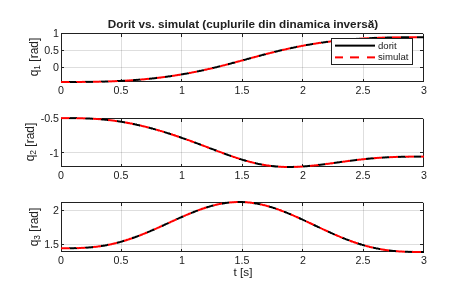


figure('Name', 'Dinamica directă - buclă deschisă');
for k = 1:3
    subplot(3,1,k);
    plot(t, Qd(k,:), 'k', t, Qs(k,:), 'r--', 'LineWidth', 1.5); grid on;
    ylabel(sprintf('q_%d [rad]', k));
    if k == 1, title('Dorit vs. simulat (cuplurile din dinamica inversă)'); legend('dorit','simulat'); end
end
xlabel('t [s]');


% 7b. Mișcare liberă (tau = 0): robotul cade sub gravitație; fără frecare
%     energia totală E = T + V trebuie să rămână constantă.
t_lib = linspace(0, 2, 201);
[Ql, dQl] = simulare_dinamica([q0; 0; 0; 0], t_lib, @(tt, x) [0; 0; 0], par);
E = zeros(size(t_lib));
for i = 1:numel(t_lib)
    [Mi, ~, ~, Vi] = model_dinamic(Ql(:,i), dQl(:,i), par);
    E(i) = 0.5*dQl(:,i).'*Mi*dQl(:,i) + Vi;
end
fprintf('Mișcare liberă: variația energiei totale %.2e J (din %.3f J)\n', max(E) - min(E), E(1));

Mișcare liberă: variația energiei totale 7.84e-07 J (din 38.630 J)


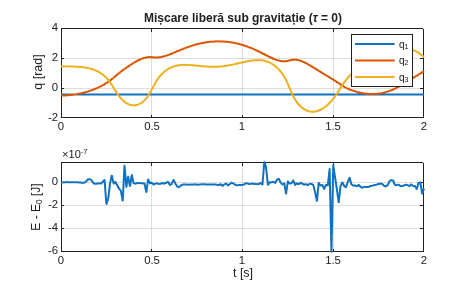


figure('Name', 'Mișcare liberă');
subplot(2,1,1); plot(t_lib, Ql, 'LineWidth', 1.5); grid on; ylabel('q [rad]'); legend('q_1','q_2','q_3');
title('Mișcare liberă sub gravitație (\tau = 0)');
subplot(2,1,2); plot(t_lib, E - E(1), 'LineWidth', 1.5); grid on; ylabel('E - E_0 [J]'); xlabel('t [s]');

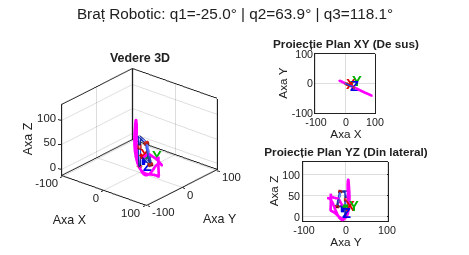

animatie(Ql, par, [], 4);

## 9. Alegerea acționărilor – motor de curent continuu + reductor planetar

Acționările se aleg pe baza cuplurilor și vitezelor obținute din modelul dinamic, pentru mișcările definite în Date_PUMA.m: mișcarea prin punctele q_puncte (spațiul cuplelor) și urmărirea traiectoriei r(t) prin trei puncte. Controlul cerut – regulator PI care comandă tensiunea motorului – presupune un motor de curent continuu cu reductor, descris de modelul din curs (structura Controler – MotoReductor – Structura model dinamic invers). De aceea s-au ales motoare maxon RE 40 cu reductoare planetare GP 52 C și GP 42 C, în locul motoarelor pas cu pas propuse inițial: acestea nu au un model de tip tensiune–viteză, iar NEMA 23 (1.26 N·m) nu acoperea cuplul static al umărului, nici cu reductorul 1:3.

Codul de mai jos rulează etapele 2, 3 și 5 ale proiectului (PUMA_simulare.m): dinamica inversă pe cele două mișcări, alegerea parametrilor PI, construirea și simularea modelului Simulink. Rezultatele sunt folosite în secțiunile următoare.

% Datele mișcărilor (aceleași ca în Date_PUMA.m); acționările implicite sunt cele de mai jos
date = struct();
date.q_static = [];
date.q_puncte = [0 -30 60; 90 -60 90; -45 -15 45; 0 -30 60];        % [grade]
date.r_puncte = [0.75 -0.35 0.55; 0.50 0.60 0.85; 0.40 0.20 0.40];   % [m]
date.T_segment = 3;  date.cot = +1;  date.miscare_libera = 0;
date.control = 1;  date.simulink = 1;  date.deschide_simulink = 0;
date.grafice = 0;  date.animatie = 0;
jurnal = evalc('rez = PUMA_simulare(date);');   % mesajele complete: disp(jurnal)
a = rez.control.act;     % acționările și regulatoarele
linii = regexp(jurnal, '[^\n]*(Verificare Simulink|Eroarea de urmărire)[^\n]*', 'match');
fprintf('%s\n', linii{:});

Verificare Simulink vs. MATLAB: diferența maximă în cuple 8.03e-06 rad
Eroarea de urmărire a lui r(t) (efector): max 8.813 mm


Cuplul static maxim apare la umăr, când brațul este întins orizontal (q2 = q3 = 0):


$$\tau_{2,st} = g\left(m_2 l_{c2} + m_3 (l_4 + l_{c3})\right) = 9.81\,(3.05 \cdot 0.20 + 2.79 \cdot 0.577) = 21.8\ \mathrm{N \cdot m}, \qquad \tau_{3,st} = g\, m_3 l_{c3} = 4.84\ \mathrm{N \cdot m}$$


Cerințele de cuplu și viteză pentru fiecare cuplă (din dinamica inversă):

[~, ~, G_oriz] = model_dinamic([0; 0; 0], [], par);      % brațul întins orizontal
dq_max = max(abs([rez.cuple.dQ, rez.urmarire.dQ]), [], 2);
cuple = {'Cupla 1', 'Cupla 2', 'Cupla 3'};
cerinte = array2table([max(abs(rez.cuple.Tau), [], 2), max(abs(rez.urmarire.Tau), [], 2), ...
    abs(G_oriz), dq_max].', 'VariableNames', cuple, 'RowNames', ...
    {'tau max, q_puncte [Nm]', 'tau max, r(t) [Nm]', 'tau static max [Nm]', 'dq max [rad/s]'})

cerinte = 4×3 table
                              Cupla 1    Cupla 2    Cupla 3
                              _______    _______    _______

    tau max, q_puncte [Nm]    4.1368     20.831      4.2367
    tau max, r(t) [Nm]        1.5213     17.949      4.5766
    tau static max [Nm]            0     21.782      4.8416
    dq max [rad/s]            1.4723     1.2333     0.95178


**Motorul ales** (toate cuplele): maxon RE 40, Ø40 mm, perii de grafit, 150 W, 24 V – nr. 148867. Datele de catalog folosite în model:

- $U_N = 24\ \mathrm{V}$, $n_0 = 7580\ \mathrm{rpm}$, $I_0 = 137\ \mathrm{mA}$ – tensiunea nominală și mersul în gol

- $M_N = 177\ \mathrm{mN \cdot m}$, $I_N = 6\ \mathrm{A}$ – cuplul și curentul maxim continuu

- $R = 0.299\ \Omega$, $L = 0.0824\ \mathrm{mH}$, $k_m = 30.2\ \mathrm{mN \cdot m/A}$, $J_{rotor} = 142\ \mathrm{g \cdot cm^2}$, constanta mecanică 4.67 ms

**Reductoarele** (planetare, maxon):

- **Cuplele 1 și 2:** GP 52 C, 230:1, 4 trepte (nr. 223101) – 30 N·m continuu, 45 N·m intermitent, randament 68 %, inerție 16.8 g·cm², max. 6000 rpm la intrare, 920 g

- **Cupla 3:** GP 42 C, 74:1, 3 trepte (nr. 203123) – 15 N·m continuu, 22 N·m intermitent, randament 72 %, inerție 15 g·cm², max. 8000 rpm la intrare, 460 g

**Linkuri de referință:** [RE 40 (148867)](https://www.maxongroup.com/maxon/view/product/148867), [GP 52 C 230:1 (223101)](https://www.maxongroup.com/maxon/view/product/223101), [GP 42 C 74:1 (203123)](https://www.maxongroup.com/maxon/view/product/203123)

Condițiile de verificare (cuplul continuu disponibil la cuplă și turația motorului):


$$M_{disp} = M_N \cdot i_r \cdot \eta \ge \tau_{nec}, \qquad M_{disp} \le M_{max,red}, \qquad n_{motor} = i_r \cdot \dot q_{max} \cdot \frac{30}{\pi} \le n_{max,red}$$


**A. Cupla 1 (rotația bazei, axa z0).** Gravitația nu încarcă această cuplă; sarcina este inerțială. Inerția brațului față de axa z0 variază între 1.4 și 2.4 kg·m² pe traiectoria r(t). Cu reductorul 230:1 inerția motorului redusă la cuplă este Ja·η·i² = 0.57 kg·m², deci raportul de inerții este cel mult 4.2; cu 74:1 ar fi fost aproximativ 40, iar bucla de reglare ar fi devenit foarte lentă. Cuplul disponibil (27.7 N·m) depășește mult cuplul necesar (4.1 N·m), iar turația maximă a motorului este 3230 rpm < 6000 rpm.

**B. Cupla 2 (umărul).** Este cupla critică: cuplul static maxim este 21.8 N·m. Cuplul continuu disponibil este 0.177 · 230 · 0.68 = 27.7 N·m (rezervă 1.27), sub limita reductorului de 30 N·m; turația maximă a motorului este 2710 rpm.

**C. Cupla 3 (cotul).** Cuplul static maxim este 4.84 N·m; cu reductorul 74:1 cuplul disponibil este 0.177 · 74 · 0.72 = 9.4 N·m (rezervă 1.95), sub limita de 15 N·m, iar turația maximă este 670 rpm. Reductorul GP 42 C are jumătate din masa lui GP 52 C, ceea ce contează la cot.

tau_nec = max(cerinte{1:3, :}, [], 1).';
verificare = array2table([a.M_nom.*a.ir.*a.ran, tau_nec, a.M_red, a.ir.*dq_max*30/pi, a.n_red].', ...
    'VariableNames', cuple, 'RowNames', {'M disponibil [Nm]', 'tau necesar [Nm]', ...
    'M max reductor [Nm]', 'n motor max [rpm]', 'n max reductor [rpm]'})

verificare = 5×3 table
                            Cupla 1    Cupla 2    Cupla 3
                            _______    _______    _______

    M disponibil [Nm]       27.683     27.683     9.4306 
    tau necesar [Nm]        4.1368     21.782     4.8416 
    M max reductor [Nm]         30         30         15 
    n motor max [rpm]       3233.7     2708.7     672.57 
    n max reductor [rpm]      6000       6000       8000 


## 10. Modelul acționării – motor cc + reductor (MotoReductor)

Inductanța bobinajului se neglijează (L/R = 0.28 ms, mult sub constanta mecanică). Ecuația electrică și ecuația de mișcare a arborelui motorului, cu cuplul cerut de structură τ redus prin reductor:


$$i = \frac{v - k_m \omega_m}{R}, \qquad J_a \dot\omega_m = k_m i - b_m \omega_m - \frac{\tau}{\eta\, i_r}, \qquad \omega_m = i_r \dot q$$


Rezultă accelerația cuplei (aceeași formă ca în modelul de la curs):


$$\ddot q = k_2 v - k_1 \dot q - k_3 \tau, \qquad k_1 = \frac{b_m + k_m^2/R}{J_a}, \quad k_2 = \frac{k_m}{J_a\, i_r R}, \quad k_3 = \frac{1}{J_a\, \eta\, i_r^2}$$


Inerția Ja cuprinde rotorul și reductorul (redus la intrare). Frecarea vâscoasă din motor se estimează din mersul în gol, unde tot cuplul motorului învinge frecarea:


$$J_a = J_{rotor} + J_{red}, \qquad b_m = \frac{k_m I_0}{\omega_0}, \quad \omega_0 = n_0 \frac{\pi}{30}$$


Cuplul τ este calculat de modelul dinamic invers al structurii (secțiunea 7) din mișcarea cuplelor; pentru motor el este un cuplu rezistent (perturbație).

coeficienti = array2table([a.Ja*1e7, a.bm, a.k1, a.k2, a.k3].', 'VariableNames', cuple, 'RowNames', ...
    {'Ja [g*cm^2]', 'bm [Nm*s/rad]', 'k1 [1/s]', 'k2 [rad/(V*s^2)]', 'k3 [1/(kg*m^2)]'})

coeficienti = 5×3 table
                         Cupla 1       Cupla 2       Cupla 3  
                        __________    __________    __________

    Ja [g*cm^2]              158.8         158.8           157
    bm [Nm*s/rad]       5.2123e-06    5.2123e-06    5.2123e-06
    k1 [1/s]                192.41        192.41        194.62
    k2 [rad/(V*s^2)]        27.654        27.654        86.937
    k3 [1/(kg*m^2)]         1.7506        1.7506        16.155


## 11. Acordarea regulatoarelor PI – alocarea polilor

Pentru acordare, cuplul τ se tratează ca perturbație, iar motorul cu reductor are funcția de transfer de la tensiune la poziție G(s). Cu regulatorul PI C(s), bucla închisă este:


$$C(s) = \frac{K_P s + K_I}{s}, \qquad G(s) = \frac{k_2}{s(s + k_1)}, \qquad H_1(s) = \frac{C(s)G(s)}{1 + C(s)G(s)} = \frac{k_2 (K_P s + K_I)}{s^3 + k_1 s^2 + k_2 K_P s + k_2 K_I}$$


Polinomul caracteristic se impune cu polii reali -p1, -p2, -p3:


$$P(s) = s^3 + k_1 s^2 + k_2 K_P s + k_2 K_I = (s + p_1)(s + p_2)(s + p_3)$$



$$\Rightarrow\quad p_3 = k_1 - p_1 - p_2, \qquad K_P = \frac{p_1 p_2 + p_1 p_3 + p_2 p_3}{k_2}, \qquad K_I = \frac{p_1 p_2 p_3}{k_2}$$


Răspunsul la perturbație are un zero în origine, deci o perturbație constantă (de exemplu gravitația) nu produce eroare staționară, iar referința treaptă este urmărită exact:


$$H_2(s) = \frac{G(s)}{1 + C(s)G(s)} = \frac{k_2 s}{s^3 + k_1 s^2 + k_2 K_P s + k_2 K_I}, \qquad q_1(\infty) = 1, \quad q_2(\infty) = 0$$


Suma polilor este fixată de motor (p1 + p2 + p3 = k1). S-au ales p1 = p2 = k1/3, deci p3 = k1/3 (pol triplu) – răspunsul cel mai rapid fără oscilații pentru suma dată.

**Inerția brațului.** G(s) conține doar motorul. La robotul din exemplul de la curs (SCARA ușor) brațul văzut de motor este neglijabil, k3·M ≈ 0.05. La structura PUMA brațul este comparabil sau mai mare decât inerția motorului redusă la cuplă: k3·M_ii = 2.5…4.2 (cupla 1), 0.7…1.4 (cupla 2), 1.9 (cupla 3). Înlocuind τ = M_ii·q̈ + … în ecuația motorului se obține (1 + k3·M_ii)·q̈ = k2·v − k1·q̇ − …, adică o inerție echivalentă. La acordare, în k1 și k2 se folosește J_ech în locul lui Ja, cu M_ii mediu pe traiectorie:


$$J_{ech} = J_a + \frac{\bar M_{ii}}{\eta\, i_r^2}$$


Cu acordarea pe motorul singur, bucla reală ar avea la cupla 1 amortizarea ζ ≈ 0.14 (aproape oscilantă); cu J_ech amortizarea minimă pe traiectorie este 0.77 (cupla 1), 0.84 (cupla 2) și 1.00 (cupla 3). Integratorul regulatorului pornește din tensiunea care menține brațul în poziția inițială, v0 = R·G(q0)/(km·ir·η), ca să nu apară o cădere la pornire.

regulatoare = array2table([a.J_ech*1e7, a.k1e, a.k2e, a.poli(:,1), a.Kp, a.Ki, a.v0, a.zeta_min].', ...
    'VariableNames', cuple, 'RowNames', {'J_ech [g*cm^2]', 'k1 cu J_ech [1/s]', 'k2 cu J_ech', ...
    'p1 = p2 = p3 [rad/s]', 'Kp [V/rad]', 'Ki [V/(rad*s)]', 'v0 [V]', 'zeta min (bucla reala)'})

regulatoare = 8×3 table
                              Cupla 1    Cupla 2    Cupla 3 
                              _______    _______    ________

    J_ech [g*cm^2]             651.14     327.18       446.7
    k1 cu J_ech [1/s]          46.925     93.389      68.401
    k2 cu J_ech                6.7442     13.422      30.555
    p1 = p2 = p3 [rad/s]       15.642      31.13        22.8
    Kp [V/rad]                 108.83      216.6      51.042
    Ki [V/(rad*s)]             567.45     2247.5      387.92
    v0 [V]                          0     -1.121    -0.53051
    zeta min (bucla reala)    0.77322    0.83881           1


## 12. Modelul Simulink – contrPUMA.slx

Modelul are aceeași structură ca modelul de la curs (contrClasic42) și este construit automat de PUMA_simulare.m din datele din Date_PUMA.m (se regenerează la fiecare rulare):

- **Poz_dorita** (From File): fișierul Poz_dorita.mat, matricea [t; q1d; q2d; q3d] (primul rând este timpul), eșantionată la 1 ms; q_d(t) rezultă din r(t) prin modelul cinematic invers.

- **Controler:** e_i = q_id − q_i → PI (blocul PID Controller în mod PI, cu Kp, Ki din secțiunea 11) → saturație ±24 V → v_i; erorile și comenzile se salvează în out.erori și out.comanda.

- **MotoReductor1…3:** blocul MATLAB Function „Acc MotoRed” cu ecuația din secțiunea 10, urmat de două integratoare (dq, q) și de amplificarea rps2rpm (turația motorului n).

- **StructuraPUMA:** blocul MATLAB Function cu modelul dinamic invers τ = M·q̈ + C·q̇ + G (aceeași funcție model_dinamic); τ revine la motoare drept cuplu rezistent. Mișcările și momentele se salvează în out.miscari și out.moMo.

**Bucla algebrică.** Motorul are nevoie de τ ca să calculeze q̈, iar structura are nevoie de q̈ ca să calculeze τ. Simulink nu poate rezolva această buclă prin blocuri MATLAB Function. În modelul de la curs bucla este ruptă cu un bloc Memory (întârziere de un pas), soluție stabilă doar dacă k3·M_ii < 1 – condiție îndeplinită la SCARA (≈ 0.05), dar nu la PUMA (până la 4.2): cu Memory simularea diverge după 0.03 s. De aceea bucla este ruptă cu un filtru de ordinul 1 pe τ, cu Tf = 1 ms (mult sub constantele de timp ale buclei, 30–65 ms), stabil pentru orice raport de inerții:


$$\tau_f(s) = \frac{\tau(s)}{T_f s + 1}, \qquad T_f = 1\ \mathrm{ms}$$


Verificare: aceeași buclă simulată direct în MATLAB, cu cuplajul motor–structură rezolvat exact, (I + K3·M)·q̈ = K2·v − K1·q̇ − K3·(C·q̇ + G), dă practic aceleași rezultate (diferența maximă în cuple este de ordinul 1e-5 rad, vezi mesajele de la secțiunea 9).

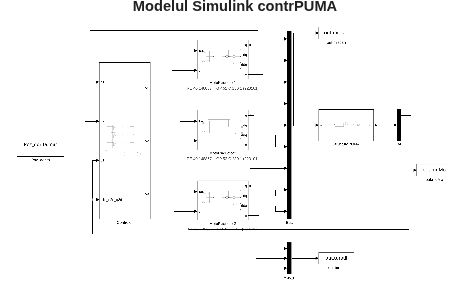

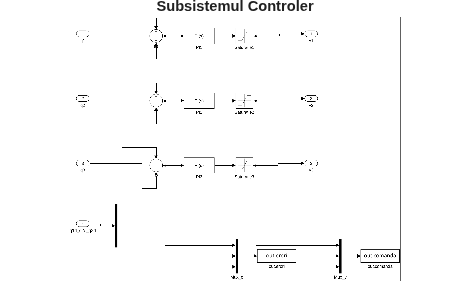

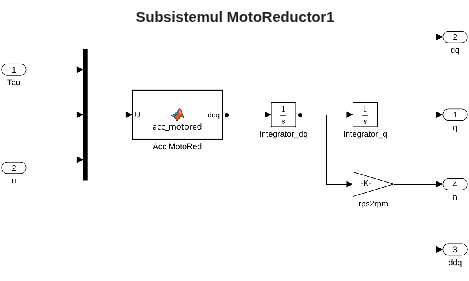

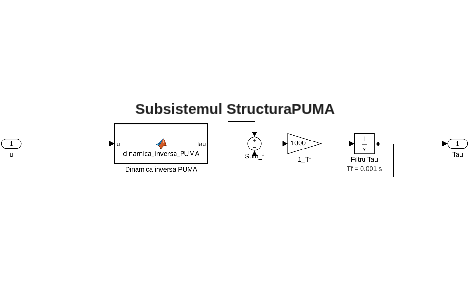

mdl = 'contrPUMA';
load_system(mdl);
sisteme = {mdl, [mdl '/Controler'], [mdl '/MotoReductor1'], [mdl '/StructuraPUMA']};
titluri = {'Modelul Simulink contrPUMA', 'Subsistemul Controler', 'Subsistemul MotoReductor1', ...
           'Subsistemul StructuraPUMA'};
for k = 1:numel(sisteme)
    fisier = [tempname '.png'];
    print(['-s' sisteme{k}], '-dpng', '-r150', fisier);
    figure('Color', 'w', 'Position', [100 100 1000 600]);
    axes('Position', [0 0 1 0.94]); image(imread(fisier)); axis image off; title(titluri{k});
    delete(fisier);
end

## 13. Rezultatele simulării în buclă închisă

Referința este traiectoria r(t) prin trei puncte (2 × 3 s, lege de grad 5), urmată de 1 s de menținere. Graficele sunt făcute din ieșirile modelului Simulink (out.miscari, out.moMo, out.erori, out.comanda).

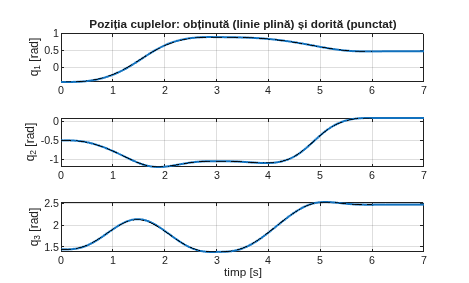

r = rez.control.res;  tc = rez.control.tc;  Qd = rez.control.Qd;
figure('Color', 'w');
for k = 1:3
    subplot(3,1,k); plot(r.t, r.Q(k,:), 'LineWidth', 1.5); hold on; plot(tc, Qd(k,:), '--k');
    grid on; ylabel(sprintf('q_%d [rad]', k));
    if k == 1, title('Poziția cuplelor: obținută (linie plină) și dorită (punctat)'); end
end
xlabel('timp [s]');

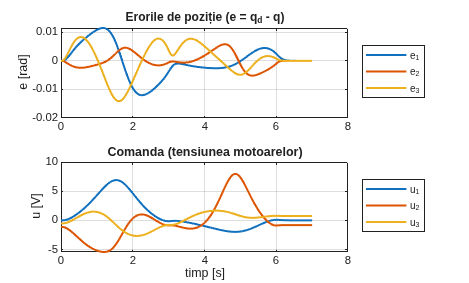


figure('Color', 'w');
subplot(2,1,1); plot(r.t, r.E, 'LineWidth', 1.5); grid on; ylabel('e [rad]');
legend('e_1', 'e_2', 'e_3', 'Location', 'eastoutside'); title('Erorile de poziție (e = q_d - q)');
subplot(2,1,2); plot(r.t, r.U, 'LineWidth', 1.5); grid on; ylabel('u [V]'); xlabel('timp [s]');
legend('u_1', 'u_2', 'u_3', 'Location', 'eastoutside'); title('Comanda (tensiunea motoarelor)');

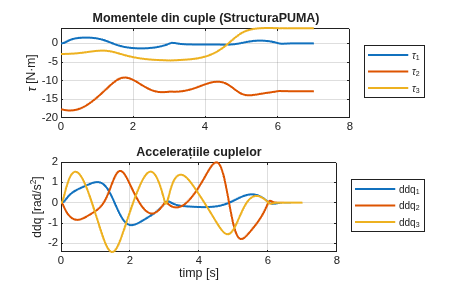


figure('Color', 'w');
subplot(2,1,1); plot(r.t, r.Tau, 'LineWidth', 1.5); grid on; ylabel('\tau [N·m]');
legend('\tau_1', '\tau_2', '\tau_3', 'Location', 'eastoutside'); title('Momentele din cuple (StructuraPUMA)');
subplot(2,1,2); plot(r.t, r.ddQ, 'LineWidth', 1.5); grid on; ylabel('ddq [rad/s^2]'); xlabel('timp [s]');
legend('ddq_1', 'ddq_2', 'ddq_3', 'Location', 'eastoutside'); title('Accelerațiile cuplelor');

Curentul, cuplul și turația motoarelor (curentul rezultă din tensiune și viteză, i = (v − km·ir·q̇)/R) și eroarea efectorului față de traiectoria r(t):

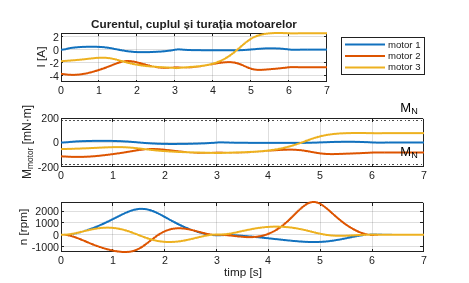

figure('Color', 'w');
subplot(3,1,1); plot(r.t, r.I, 'LineWidth', 1.5); grid on; ylabel('I [A]');
legend('motor 1', 'motor 2', 'motor 3', 'Location', 'eastoutside'); title('Curentul, cuplul și turația motoarelor');
subplot(3,1,2); plot(r.t, 1000*r.Mm, 'LineWidth', 1.5); hold on;
yline(1000*a.M_nom(1)*[-1 1], ':k', 'M_N'); grid on; ylabel('M_{motor} [mN·m]');
subplot(3,1,3); plot(r.t, r.n, 'LineWidth', 1.5); grid on; ylabel('n [rpm]'); xlabel('timp [s]');

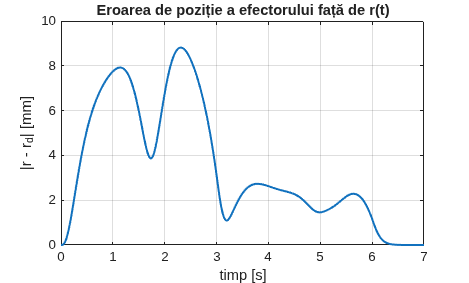


figure('Color', 'w');
plot(r.t, 1000*r.eroare_r, 'LineWidth', 1.5); grid on;
xlabel('timp [s]'); ylabel('|r - r_d| [mm]'); title('Eroarea de poziție a efectorului față de r(t)');


rms_ = @(x) sqrt(trapz(r.t, x.^2, 2)/(r.t(end) - r.t(1)));
rezultate = array2table([max(abs(r.E), [], 2), max(abs(r.U), [], 2), a.U_nom, rms_(r.I), a.I_nom, ...
    max(abs(r.n), [], 2), a.n_red, max(abs(r.Tau), [], 2)].', 'VariableNames', cuple, 'RowNames', ...
    {'e max [rad]', 'u max [V]', 'U_N [V]', 'I rms [A]', 'I_N [A]', 'n max [rpm]', 'n max reductor [rpm]', 'tau max [Nm]'})

rezultate = 8×3 table
                            Cupla 1     Cupla 2     Cupla 3 
                            _______    _________    ________

    e max [rad]             0.01202    0.0058199    0.014115
    u max [V]                6.8964         7.95      2.6761
    U_N [V]                      24           24          24
    I rms [A]               0.21756        2.766      2.1653
    I_N [A]                       6            6           6
    n max [rpm]                2185       2763.3      680.59
    n max reductor [rpm]       6000         6000        8000
    tau max [Nm]             1.5491       17.981      4.5816


fprintf('Eroarea maximă a efectorului: %.2f mm\n', 1000*max(r.eroare_r));

Eroarea maximă a efectorului: 8.81 mm


Erorile maxime în cuple sunt de ordinul 1e-2 rad; apar în timpul accelerărilor și scad la zero după oprire, datorită componentei integrale. Eroarea efectorului rămâne sub 9 mm. Tensiunile sunt sub 8 V din 24 V, curenții efectivi sub 2.8 A din 6 A, iar turațiile sub 2800 rpm din 6000 rpm, deci acționările sunt corect dimensionate. Eroarea scade cu pătratul duratei mișcării: pentru T_segment = 6 s devine de aproximativ patru ori mai mică. Animația robotului pentru mișcarea obținută prin control se vede, la rularea Date_PUMA.m, în fereastra de vizualizare, tabul „5. Control PI”.

## 14. Concluzii

- Modelul geometric folosește direct matricile 0_1T, 1_2T, 2_3T, 3_eT din calcul; modelul invers reface unghiurile cu eroare de ordinul 1e-16.

- Modelul cinematic (Jacobian, dJ) și cel invers transformă traiectoria impusă r(t) în referințe pentru cuple.

- Modelul dinamic a fost verificat prin antisimetria dM/dt − 2C, conservarea energiei și reproducerea traiectoriei în buclă deschisă.

- Acționările (maxon RE 40 + GP 52 C 230:1 la cuplele 1 și 2, GP 42 C 74:1 la cupla 3) au fost alese din cuplurile și vitezele modelului dinamic; cuplul static al umărului (21.8 N·m) este acoperit cu rezerva 1.27.

- Regulatoarele PI au fost acordate prin alocarea polilor (pol triplu), folosind inerția echivalentă motor + braț; amortizarea reală minimă este 0.77.

- Modelul Simulink urmează structura de la curs (Controler – MotoReductor – Structura model dinamic invers); bucla algebrică este ruptă cu un filtru de 1 ms, deoarece blocul Memory diverge pentru raportul de inerții al structurii PUMA.

- Urmărirea lui r(t): eroarea maximă în cuple este de ordinul 1e-2 rad, la efector sub 9 mm, iar în regim staționar eroarea este nulă.

- Pași următori posibili: modelul în Simscape Multibody (aceleași dimensiuni și mase) comparat cu modelul analitic; o componentă de compensare a gravitației sau de feed-forward pentru erori mai mici.

## 15. Funcții locale

Funcțiile folosite de script (secțiunile 1–8) sunt definite mai jos; etapa de control (secțiunile 9–13) folosește funcțiile din PUMA_simulare.m.

## Parametrii robotului

function par = parametri_PUMA()
% Parametrii geometrici și inerțiali ai structurii PUMA (3 cuple R)
%   {0} --[Rz(q1), t=(0,0,l1)]--> {1} --[Ry(q2), t=(l3,0,l2)]--> {2}
%       --[Ry(q3), t=(l4,0,0)]--> {3} --[I3,    t=(le,0,0)]--> {e}
% Elementele sunt cilindri omogeni de rază "raza" și densitate "rho"
% (aceleași valori se folosesc în Simscape Multibody).
%   Element 1 (q1): coloana verticală l2 + brațul orizontal l3
%   Element 2 (q2): bara l4
%   Element 3 (q3): bara le + sarcina utilă mp în punctul E

% Dimensiuni [m]
par.l1 = 0.40;      % înălțimea bazei fixe (până la cupla 1)
par.l2 = 0.20;      % coloana verticală a elementului 1
par.l3 = 0.30;      % brațul orizontal al elementului 1 (până la cupla 2)
par.l4 = 0.40;      % elementul 2 (cupla 2 -> cupla 3)
par.le = 0.30;      % elementul 3 (cupla 3 -> efector E)

% Material și secțiune
par.raza = 0.030;   % raza secțiunii [m]
par.rho  = 2700;    % densitate [kg/m^3] (aluminiu)
par.mp   = 0.5;     % sarcina utilă din E [kg]
par.g    = 9.81;    % accelerația gravitațională [m/s^2] (pe -z)
par.Fv   = [0; 0; 0];  % frecare vâscoasă în cuple [N·m·s/rad]

r = par.raza;
masa = @(L) par.rho*pi*r^2*L;

% Element 1: doar inerția față de axa z0 contează
par.m1a = masa(par.l2);
par.m1b = masa(par.l3);
par.I1zz = par.m1a*r^2/2 + par.m1b*(3*r^2 + par.l3^2)/12 + par.m1b*(par.l3/2)^2;

% Element 2: bară l4 pe axa x2, CM la l4/2
par.m2  = masa(par.l4);
par.lc2 = par.l4/2;
par.I2  = [par.m2*r^2/2, par.m2*(3*r^2 + par.l4^2)/12, par.m2*(3*r^2 + par.l4^2)/12];  % [Ixx Iyy Izz] față de CM

% Element 3: bară le + sarcina mp în E
mb = masa(par.le);
par.m3  = mb + par.mp;
par.lc3 = (mb*par.le/2 + par.mp*par.le)/par.m3;
Iyy3 = mb*(3*r^2 + par.le^2)/12 + mb*(par.le/2 - par.lc3)^2 + par.mp*(par.le - par.lc3)^2;
par.I3  = [mb*r^2/2, Iyy3, Iyy3];
par.mb3 = mb;
end

## Model geometric direct

function [p, T0e, T] = geometric(q, par, f)
% [p, T0e, T] = geometric(q, par, f)
%   f = 0 doar calcul, f = 1 deschide vizualizarea robotului
% Matricile din calcul:
%   0_1T = [Rz(q1) (0,0,l1)]   1_2T = [Ry(q2) (l3,0,l2)]
%   2_3T = [Ry(q3) (l4,0,0)]   3_eT = [I3     (le,0,0)]
%   0_2T = 0_1T*1_2T,  0_3T = 0_2T*2_3T,  0_eT = 0_3T*3_eT
if nargin < 3, f = 0; end
Rz = @(a) [cos(a) -sin(a) 0;  sin(a) cos(a) 0;  0 0 1];
Ry = @(a) [cos(a) 0 sin(a);  0 1 0;  -sin(a) 0 cos(a)];
omog = @(Rm, tv) [Rm, tv(:); 0 0 0 1];

T01 = omog(Rz(q(1)), [0; 0; par.l1]);
T12 = omog(Ry(q(2)), [par.l3; 0; par.l2]);
T23 = omog(Ry(q(3)), [par.l4; 0; 0]);
T3e = omog(eye(3),   [par.le; 0; 0]);

T02 = T01*T12;
T03 = T02*T23;
T0e = T03*T3e;

p = T0e(1:3, 4);
T = struct('T01', T01, 'T02', T02, 'T03', T03, 'T0e', T0e);

if f == 1
    vizualizare_robot(q, par);
end
end

## Model geometric invers

function q = geometric_invers(p, par, cot)
% cot = +1 cot sus (q3 > 0, implicit), -1 cot jos (q3 < 0)
%   q1 = atan2(y, x)
%   rho = sqrt(x^2+y^2) - l3 = l4*c2 + le*c23
%   h   = l1 + l2 - z        = l4*s2 + le*s23   (mecanism plan 2R)
if nargin < 3, cot = 1; end
x = p(1); y = p(2); z = p(3);
q1  = atan2(y, x);
rho = sqrt(x^2 + y^2) - par.l3;
h   = par.l1 + par.l2 - z;
c3 = (rho^2 + h^2 - par.l4^2 - par.le^2) / (2*par.l4*par.le);
if abs(c3) > 1
    error('geometric_invers: punctul [%.3f %.3f %.3f] este în afara spațiului de lucru.', x, y, z);
end
s3 = cot*sqrt(1 - c3^2);
q3 = atan2(s3, c3);
q2 = atan2(h, rho) - atan2(par.le*s3, par.l4 + par.le*c3);
q = [q1; q2; q3];
end

## Jacobian

function [J, dJ] = jacobian_PUMA(q, dq, par)
% J = [Jv; Jw] (6x3):  [v; w] = J*dq,   [a; e] = J*ddq + dJ*dq
%   r = l3 + l4*c2 + le*c23,   a = l4*s2 + le*s23
%   Jv = [ -s1*r  -c1*a  -c1*le*s23 ;  c1*r  -s1*a  -s1*le*s23 ;  0  -(l4*c2+le*c23)  -le*c23 ]
%   Jw = [ 0 -s1 -s1 ;  0 c1 c1 ;  1 0 0 ]
if nargin < 2 || isempty(dq), dq = [0; 0; 0]; end
l3 = par.l3; l4 = par.l4; le = par.le;
s1 = sin(q(1)); c1 = cos(q(1));
s2 = sin(q(2)); c2 = cos(q(2));
s23 = sin(q(2)+q(3)); c23 = cos(q(2)+q(3));
dq1 = dq(1); dq2 = dq(2); dq3 = dq(3);

r  = l3 + l4*c2 + le*c23;
a  = l4*s2 + le*s23;
b  = le*s23;
cc = l4*c2 + le*c23;
c  = le*c23;

Jv = [-s1*r, -c1*a, -c1*b;
       c1*r, -s1*a, -s1*b;
       0,    -cc,   -c  ];
Jw = [0, -s1, -s1;
      0,  c1,  c1;
      1,  0,   0 ];
J = [Jv; Jw];

dr  = -a*dq2 - b*dq3;
da  =  cc*dq2 + c*dq3;
db  =  c*(dq2 + dq3);
dcc = -a*dq2 - b*dq3;
dc  = -b*(dq2 + dq3);
dJv = [-c1*dq1*r - s1*dr,   s1*dq1*a - c1*da,   s1*dq1*b - c1*db;
       -s1*dq1*r + c1*dr,  -c1*dq1*a - s1*da,  -c1*dq1*b - s1*db;
        0,                 -dcc,               -dc            ];
dJw = [0, -c1*dq1, -c1*dq1;
       0, -s1*dq1, -s1*dq1;
       0,  0,       0     ];
dJ = [dJv; dJw];
end

## Generare traiectorie

function [pvc, t] = traiect(q, T, N, grad, flag, nume)
% q - n x 2 [start, final]; grad 3 (cubic) sau 5; pvc = [P; V; A]
%   grad 3: s = 3*tau^2 - 2*tau^3
%   grad 5: s = 10*tau^3 - 15*tau^4 + 6*tau^5     (tau = t/T)
if nargin < 4 || isempty(grad), grad = 5; end
if nargin < 5, flag = 0; end
n = size(q, 1);
if nargin < 6
    nume = arrayfun(@(k) sprintf('q_%d', k), 1:n, 'UniformOutput', false);
end
t   = linspace(0, T, N);
tau = t/T;
switch grad
    case 3
        s = 3*tau.^2 - 2*tau.^3;  ds = (6*tau - 6*tau.^2)/T;  dds = (6 - 12*tau)/T^2;
    case 5
        s   = 10*tau.^3 - 15*tau.^4 + 6*tau.^5;
        ds  = (30*tau.^2 - 60*tau.^3 + 30*tau.^4)/T;
        dds = (60*tau - 180*tau.^2 + 120*tau.^3)/T^2;
    otherwise
        error('traiect: grad trebuie să fie 3 sau 5');
end
dq = q(:,2) - q(:,1);
P = q(:,1) + dq*s;  V = dq*ds;  A = dq*dds;
pvc = [P; V; A];

if flag == 1
    figure('Name', 'Traiectorie');
    titluri = {'poziție', 'viteză', 'accelerație'};
    date = {P, V, A};
    for i = 1:n
        for k = 1:3
            subplot(n, 3, (i-1)*3 + k);
            plot(t, date{k}(i,:), 'LineWidth', 1.5); grid on;
            title([nume{i} ' - ' titluri{k}]);
            if i == n, xlabel('t [s]'); end
        end
    end
end
end

## Model cinematic direct

function [P, V, A, W] = cinematica_directa(Q, dQ, ddQ, t, par, f)
% p = MGD(q),  v = Jv*dq,  a = Jv*ddq + dJv*dq,  w = Jw*dq
if nargin < 6, f = 0; end
N = size(Q, 2);
P = zeros(3, N); V = P; A = P; W = P;
for i = 1:N
    P(:,i) = geometric(Q(:,i), par, 0);
    [J, dJ] = jacobian_PUMA(Q(:,i), dQ(:,i), par);
    v6 = J*dQ(:,i);
    a6 = J*ddQ(:,i) + dJ*dQ(:,i);
    V(:,i) = v6(1:3);  W(:,i) = v6(4:6);  A(:,i) = a6(1:3);
end
if f == 1
    figure('Name', 'Model cinematic direct');
    subplot(2,2,1); plot(t, P, 'LineWidth', 1.5); grid on; title('Poziția efectorului');  legend('x','y','z'); ylabel('[m]');
    subplot(2,2,2); plot(t, V, 'LineWidth', 1.5); grid on; title('Viteza liniară');       legend('V_x','V_y','V_z'); ylabel('[m/s]');
    subplot(2,2,3); plot(t, A, 'LineWidth', 1.5); grid on; title('Accelerația liniară');  legend('a_x','a_y','a_z'); ylabel('[m/s^2]'); xlabel('t [s]');
    subplot(2,2,4); plot(t, W, 'LineWidth', 1.5); grid on; title('Viteza unghiulară');    legend('\omega_x','\omega_y','\omega_z'); ylabel('[rad/s]'); xlabel('t [s]');
end
end

## Model cinematic invers (urmărire r(t))

function [Q, dQ, ddQ] = cinematica_inversa(R, dR, ddR, par, cot)
% q = MGI(r),  dq = Jv^-1*dr,  ddq = Jv^-1*(ddr - dJv*dq)
if nargin < 5, cot = 1; end
N = size(R, 2);
Q = zeros(3, N); dQ = Q; ddQ = Q;
for i = 1:N
    q = geometric_invers(R(:,i), par, cot);
    J = jacobian_PUMA(q, [], par);
    Jv = J(1:3,:);
    if rcond(Jv) < 1e-8
        warning('cinematica_inversa: configurație singulară la pasul %d', i);
    end
    dq = Jv \ dR(:,i);
    [~, dJ] = jacobian_PUMA(q, dq, par);
    ddq = Jv \ (ddR(:,i) - dJ(1:3,:)*dq);
    Q(:,i) = q; dQ(:,i) = dq; ddQ(:,i) = ddq;
end
Q(1,:) = unwrap(Q(1,:));   % evită saltul de 2*pi al lui atan2
end

## Model dinamic

function [M, C, G, V] = model_dinamic(q, dq, par)
% M(q)*ddq + C(q,dq)*dq + G(q) + Fv*dq = tau     (Lagrange)
%   r_c2 = l3 + lc2*c2,           z_c2 = l1 + l2 - lc2*s2
%   r_c3 = l3 + l4*c2 + lc3*c23,  z_c3 = l1 + l2 - l4*s2 - lc3*s23
%   w2 = [-s2*dq1; dq2; c2*dq1],  w3 = [-s23*dq1; dq2+dq3; c23*dq1]  (în axele proprii)
if nargin < 2 || isempty(dq), dq = [0; 0; 0]; end
l1 = par.l1; l2 = par.l2; l3 = par.l3; l4 = par.l4;
m2 = par.m2; m3 = par.m3; lc2 = par.lc2; lc3 = par.lc3; g = par.g;
I2xx = par.I2(1); I2yy = par.I2(2); I2zz = par.I2(3);
I3xx = par.I3(1); I3yy = par.I3(2); I3zz = par.I3(3);
s2 = sin(q(2)); c2 = cos(q(2)); s3 = sin(q(3)); c3 = cos(q(3));
s23 = sin(q(2)+q(3)); c23 = cos(q(2)+q(3));
dq1 = dq(1); dq2 = dq(2); dq3 = dq(3);

rc2 = l3 + lc2*c2;
rc3 = l3 + l4*c2 + lc3*c23;

% Matricea maselor
M11 = par.I1zz + I2xx*s2^2 + I2zz*c2^2 + I3xx*s23^2 + I3zz*c23^2 + m2*rc2^2 + m3*rc3^2;
M22 = I2yy + m2*lc2^2 + I3yy + m3*(l4^2 + lc3^2 + 2*l4*lc3*c3);
M23 = I3yy + m3*(lc3^2 + l4*lc3*c3);
M33 = I3yy + m3*lc3^2;
M = [M11 0   0;
     0   M22 M23;
     0   M23 M33];

% Matricea Coriolis/centrifugală (Christoffel)
% h2 = 1/2*dM11/dq2,  h3 = 1/2*dM11/dq3,  h = m3*l4*lc3*s3
h2 = (I2xx - I2zz)*s2*c2 + (I3xx - I3zz)*s23*c23 - m2*rc2*lc2*s2 - m3*rc3*(l4*s2 + lc3*s23);
h3 = (I3xx - I3zz)*s23*c23 - m3*rc3*lc3*s23;
h  = m3*l4*lc3*s3;
C = [ h2*dq2 + h3*dq3,  h2*dq1,   h3*dq1;
     -h2*dq1,          -h*dq3,   -h*(dq2 + dq3);
     -h3*dq1,           h*dq2,    0            ];

% Vectorul gravitațional G = dV/dq
G = [0;
     -g*(m2*lc2*c2 + m3*(l4*c2 + lc3*c23));
     -g*m3*lc3*c23];

% Energia potențială
V = g*(m2*(l1 + l2 - lc2*s2) + m3*(l1 + l2 - l4*s2 - lc3*s23));
end

## Dinamica inversă

function Tau = dinamica_inversa(Q, dQ, ddQ, t, par, f)
% tau = M*ddq + C*dq + G + Fv*dq
if nargin < 6, f = 0; end
N = size(Q, 2);
Tau = zeros(3, N); Tin = Tau; Tcor = Tau; Tgr = Tau;
for i = 1:N
    [M, C, G] = model_dinamic(Q(:,i), dQ(:,i), par);
    Tin(:,i)  = M*ddQ(:,i);
    Tcor(:,i) = C*dQ(:,i);
    Tgr(:,i)  = G;
    Tau(:,i)  = Tin(:,i) + Tcor(:,i) + Tgr(:,i) + par.Fv(:).*dQ(:,i);
end
if f == 1
    figure('Name', 'Dinamica inversă');
    for k = 1:3
        subplot(3,1,k);
        plot(t, Tau(k,:), 'k', 'LineWidth', 2); hold on;
        plot(t, Tin(k,:), '--', t, Tcor(k,:), '--', t, Tgr(k,:), '--', 'LineWidth', 1.2);
        grid on; ylabel(sprintf('\\tau_%d [N·m]', k));
        if k == 1
            title('Cuplurile din cuple');
            legend('\tau total', 'M·ddq', 'C·dq', 'G', 'Location', 'best');
        end
    end
    xlabel('t [s]');
end
end

## Dinamica directă

function dx = dinamica_directa(t, x, tau_fun, par)
% x = [q; dq],  ddq = M^-1*(tau - C*dq - G - Fv*dq)
% tau_fun(t, x): cuplu în buclă deschisă, zero, sau (mai târziu) legea de reglare
q  = x(1:3);
dq = x(4:6);
tau = tau_fun(t, x);
[M, C, G] = model_dinamic(q, dq, par);
ddq = M \ (tau(:) - C*dq - G - par.Fv(:).*dq);
dx = [dq; ddq];
end

function [Q, dQ] = simulare_dinamica(x0, t, tau_fun, par)
% integrarea modelului dinamic cu ode45
opt = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);
[~, X] = ode45(@(tt, x) dinamica_directa(tt, x, tau_fun, par), t, x0(:), opt);
Q  = X(:, 1:3).';
dQ = X(:, 4:6).';
end

## Vizualizare

function h = vizualizare_robot(q, par, Rdorit)
% Fereastra "Braț Robotic - Vizualizare Complexă":
%   stânga  - vedere 3D
%   dreapta - proiecție în planul XY (de sus) și în planul YZ (din lateral)
% Robotul este desenat din cilindri (elemente albastre, cuple roșii),
% cu sistemul de coordonate al efectorului {e}. Unitățile afișate sunt cm.
if nargin < 3, Rdorit = []; end
h.fig = figure('Name', 'Braț Robotic - Vizualizare Complexă', 'NumberTitle', 'off', ...
               'Color', 'w', 'Position', [80 80 1250 680]);
h.ax(1) = subplot(2, 2, [1 3]);
h.ax(2) = subplot(2, 2, 2);
h.ax(3) = subplot(2, 2, 4);
titluri = {'Vedere 3D', 'Proiecție Plan XY (De sus)', 'Proiecție Plan YZ (Din lateral)'};
vederi  = {[40 25], [0 90], [90 0]};

piese = piese_robot(par);
L = 100*(par.l3 + par.l4 + par.le) + 3;                       % raza zonei de lucru [cm]
zmin = min(0, 100*(par.l1 + par.l2 - par.l4 - par.le)) - 3;
zmax = 100*(par.l1 + par.l2 + par.l4 + par.le) + 3;

for k = 1:3
    ax = h.ax(k);
    hold(ax, 'on');
    h.obiecte{k} = creeaza_piese(ax, piese);
    h.urma(k) = plot3(ax, NaN, NaN, NaN, 'm', 'LineWidth', 2);
    if ~isempty(Rdorit)
        plot3(ax, 100*Rdorit(1,:), 100*Rdorit(2,:), 100*Rdorit(3,:), 'k:', 'LineWidth', 1.2);
    end
    axis(ax, 'equal');
    axis(ax, [-L L -L L zmin zmax]);
    grid(ax, 'on'); box(ax, 'on');
    xlabel(ax, 'Axa X'); ylabel(ax, 'Axa Y'); zlabel(ax, 'Axa Z');
    title(ax, titluri{k});
    view(ax, vederi{k});
    light('Parent', ax, 'Position', [1 -1 2], 'Style', 'infinite');
    light('Parent', ax, 'Position', [-1 1 1], 'Style', 'infinite');
end
h.piese = piese;
h.titlu = sgtitle(h.fig, '');
actualizare_robot(h, q, par);
end

function actualizare_robot(h, q, par, P)
% Mută robotul în configurația q (și desenează urma efectorului P, dacă există)
[~, ~, T] = geometric(q, par, 0);
cm = @(Tm) [Tm(1:3,1:3), 100*Tm(1:3,4); 0 0 0 1];
TT = {eye(4), cm(T.T01), cm(T.T02), cm(T.T03), cm(T.T0e)};   % cadrele 0, 1, 2, 3, e
for k = 1:numel(h.ax)
    ob = h.obiecte{k};
    for j = 1:numel(h.piese)
        pc = h.piese(j);
        Tm = TT{pc.cadru + 1};
        pts = Tm(1:3,1:3)*[pc.X(:).'; pc.Y(:).'; pc.Z(:).'] + Tm(1:3,4);
        sz = size(pc.X);
        if strcmp(pc.tip, 'text')
            set(ob(j), 'Position', pts.');
        else
            set(ob(j), 'XData', reshape(pts(1,:), sz), 'YData', reshape(pts(2,:), sz), ...
                       'ZData', reshape(pts(3,:), sz));
        end
    end
    if nargin >= 4 && ~isempty(P)
        set(h.urma(k), 'XData', 100*P(1,:), 'YData', 100*P(2,:), 'ZData', 100*P(3,:));
    end
end
qg = q*180/pi;
set(h.titlu, 'String', sprintf('Braț Robotic: q1=%.1f° | q2=%.1f° | q3=%.1f°', qg(1), qg(2), qg(3)));
end

function piese = piese_robot(par)
% Geometria robotului (în cm), fiecare piesă descrisă în cadrul ei:
%   cadru 0 = baza fixă, 1 = {1}, 2 = {2}, 3 = {3}, 4 = {e}
s = 100;
r  = 100*par.raza;                      % raza elementelor [cm]
rc = 1.35*r;                            % raza cuplelor
albastru = [0.15 0.25 0.85];
rosu     = [0.85 0.15 0.15];
l1 = s*par.l1; l2 = s*par.l2; l3 = s*par.l3; l4 = s*par.l4; le = s*par.le;

piese = struct('cadru', {}, 'tip', {}, 'X', {}, 'Y', {}, 'Z', {}, 'culoare', {}, 'text', {});
piese = adauga_cilindru(piese, 0, [0 0 0], [0 0 0.6], 1.8*r, rosu);        % placa de bază
piese = adauga_cilindru(piese, 0, [0 0 0], [0 0 l1-rc], r, albastru);      % coloana bazei
piese = adauga_cilindru(piese, 1, [0 0 -rc], [0 0 rc], rc, rosu);          % cupla 1 (axa z)
piese = adauga_cilindru(piese, 1, [0 0 rc], [0 0 l2], r, albastru);        % element 1 - vertical
piese = adauga_sfera(piese, 1, [0 0 l2], r, albastru);                      % colț element 1
piese = adauga_cilindru(piese, 1, [0 0 l2], [l3 0 l2], r, albastru);       % element 1 - orizontal
piese = adauga_cilindru(piese, 2, [0 -rc 0], [0 rc 0], rc, rosu);          % cupla 2 (axa y)
piese = adauga_cilindru(piese, 2, [0 0 0], [l4 0 0], r, albastru);         % element 2
piese = adauga_cilindru(piese, 3, [0 -rc 0], [0 rc 0], rc, rosu);          % cupla 3 (axa y)
piese = adauga_cilindru(piese, 3, [0 0 0], [le 0 0], 0.8*r, albastru);     % element 3

% sistemul de coordonate al efectorului {e}
La = max(0.5*le, 4);
axe = {[La 0 0], [0 La 0], [0 0 La]};
culori = {[0.9 0 0], [0 0.7 0], [0 0 0.9]};
etichete = {'X', 'Y', 'Z'};
for k = 1:3
    v = axe{k};
    piese(end+1) = struct('cadru', 4, 'tip', 'linie', 'X', [0 v(1)], 'Y', [0 v(2)], ...
                          'Z', [0 v(3)], 'culoare', culori{k}, 'text', '');
    piese(end+1) = struct('cadru', 4, 'tip', 'text', 'X', 1.15*v(1), 'Y', 1.15*v(2), ...
                          'Z', 1.15*v(3), 'culoare', culori{k}, 'text', etichete{k});
end
end

function piese = adauga_cilindru(piese, cadru, p1, p2, r, culoare)
% Cilindru (cu capace) între p1 și p2, în cadrul "cadru"
n = 24;
th = linspace(0, 2*pi, n+1);
d = p2(:) - p1(:);  Lc = norm(d);  w = d/Lc;
if abs(w(1)) < 0.9, a = [1; 0; 0]; else, a = [0; 1; 0]; end
u = cross(a, w); u = u/norm(u);  v = cross(w, u);
Rm = [u v w];
% manta + capace: rândurile = (centru jos, margine jos, margine sus, centru sus)
rr = [0; r; r; 0] * ones(1, n+1);
zz = [0; 0; Lc; Lc] * ones(1, n+1);
xl = rr .* (ones(4,1)*cos(th));
yl = rr .* (ones(4,1)*sin(th));
pts = Rm*[xl(:).'; yl(:).'; zz(:).'] + p1(:);
piese(end+1) = struct('cadru', cadru, 'tip', 'suprafata', 'X', reshape(pts(1,:), 4, n+1), ...
                      'Y', reshape(pts(2,:), 4, n+1), 'Z', reshape(pts(3,:), 4, n+1), ...
                      'culoare', culoare, 'text', '');
end

function piese = adauga_sfera(piese, cadru, c, r, culoare)
[X, Y, Z] = sphere(16);
piese(end+1) = struct('cadru', cadru, 'tip', 'suprafata', 'X', r*X + c(1), 'Y', r*Y + c(2), ...
                      'Z', r*Z + c(3), 'culoare', culoare, 'text', '');
end

function ob = creeaza_piese(ax, piese)
ob = gobjects(1, numel(piese));
for j = 1:numel(piese)
    pc = piese(j);
    switch pc.tip
        case 'suprafata'
            ob(j) = surface(ax, pc.X, pc.Y, pc.Z, 'FaceColor', pc.culoare, 'EdgeColor', 'none', ...
                            'FaceLighting', 'gouraud', 'AmbientStrength', 0.5);
        case 'linie'
            ob(j) = plot3(ax, pc.X, pc.Y, pc.Z, 'Color', pc.culoare, 'LineWidth', 2.5);
        case 'text'
            ob(j) = text(ax, pc.X, pc.Y, pc.Z, pc.text, 'Color', pc.culoare, ...
                         'FontWeight', 'bold', 'FontSize', 11);
    end
end
end

function animatie(Q, par, Rdorit, pas)
% Animația robotului în fereastra de vizualizare complexă
%   Q - 3 x N coordonatele cuplelor; Rdorit - traiectoria dorită (opțional)
if nargin < 3, Rdorit = []; end
if nargin < 4, pas = 2; end
N = size(Q, 2);
P = zeros(3, N);
for i = 1:N
    P(:,i) = geometric(Q(:,i), par, 0);
end
h = vizualizare_robot(Q(:,1), par, Rdorit);
for i = unique([1:pas:N, N])
    actualizare_robot(h, Q(:,i), par, P(:,1:i));
    drawnow;
    pause(0.01);
end
end